clear all

rng(1);
timesteps = 20;
t=linspace(0,1,timesteps+1)';
t(end)=[]

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500



output1 = sin(exp(2*t)+sin(10*t).^2+3*cos(3*t)+0.5*rand(timesteps,1));
output2= cos(5*t)+0.5*rand(timesteps,1)

output2 =     1.4004
    1.4530
    1.0343
    1.0779
    0.9785
    0.7626
    0.1133
   -0.1587
   -0.3312
   -0.1891


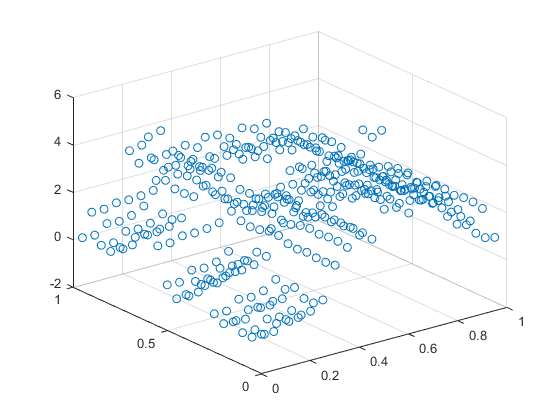

for in1 = 1:timesteps
   for in2 = 1:timesteps 
output_curve(in1,in2) = sqrt(2+(output1(in1)+1)^2+(2+output2(in2)))+3*sin(output1(in1)*output2(in2))+output2(in2)*output1(in1)+output2(in2);
   end
end
% output_curve = outproduct(output1,output2);
[X,Y] = meshgrid(t,t);
x=X(:);
y=Y(:);
z = output_curve(:);
scatter3(x,y,z);

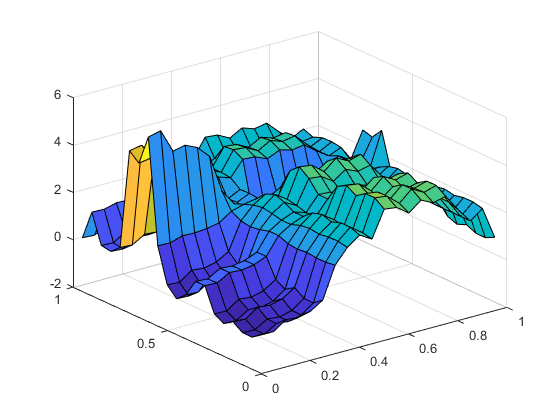

surf(t,t,output_curve);


AA = [x y];

trainz = randperm(timesteps^2,300);
testz = setdiff(1:timesteps^2, trainz);
featurez= AA(trainz,:);
tfeaturez= AA(testz,:);
zeta = z(trainz,:);
tlabels = z(testz,:);

[N, d]=size(featurez); 

nn = 2;  %degree B-spline
knotintervals = 8;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d

Pcount = 100

% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
R=2;
r=R*ones(1,d+1);

% %  r(d-1)=nnn^2;
r(1) = 1;  r(2)=nnn;  r(d)=nnn; r(d+1)=1;
% r(2)=10;
disp(r)

     1    10     1




n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

difforder=2

difforder = 2

P = diff(eye(nnn),difforder);
PP = P'*P;

res1=[];
res2=[];
MAXITR = 2*d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

lambda = 0.01

lambda = 0.0100

 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            
% nselect = floor(((itr+1)/MAXITR)^4*(N));
% dataselect = randperm((N),nselect);
dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%        
                   
%         -------------------difference penalty 
        for j=1:d
        Csize = TN.n(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.n(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
%         ----------------------- 
        D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));  
            AAA=  A'*A;
            gamma1= sqrt(trace(AAA)/trace(W{1}))
            gamma2= sqrt(trace(AAA)/trace(W{2}))

%         g=pinv(AAA + lambda*(gamma1*W{1} + gamma2*W{2}))*(A'*zeta(dataselect,:));

        g=pinv(AAA + lambda*(WWW))*(A'*zeta(dataselect,:));
        
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-y(dataselect,:))^2; % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   

        
end  

gamma1 = 0.1371

gamma2 = 0.4852

    "iteration:"    "2"    "0.015296"



gamma1 = 0.4351

gamma2 = 0.4351

    "iteration:"    "3"    "0.021797"



gamma1 = 0.4351

gamma2 = 0.4351

    "iteration:"    "4"    "0.033569"



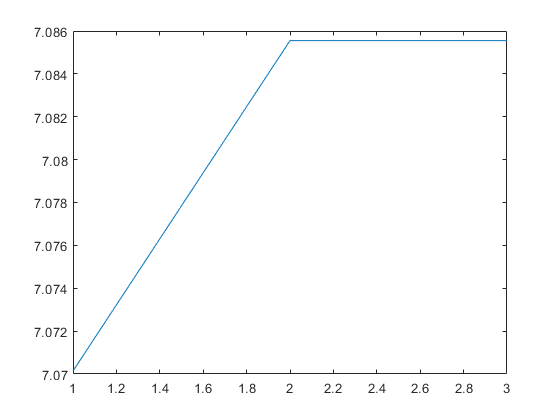

plot(log(res1))

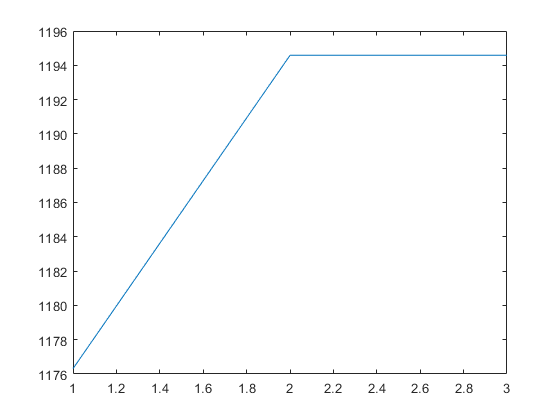

plot((res1))

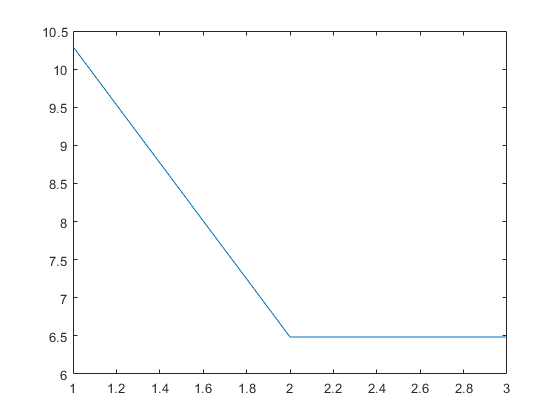

plot(log(res2))

tfeaturez= [x y];
[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;

for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,1);

for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end

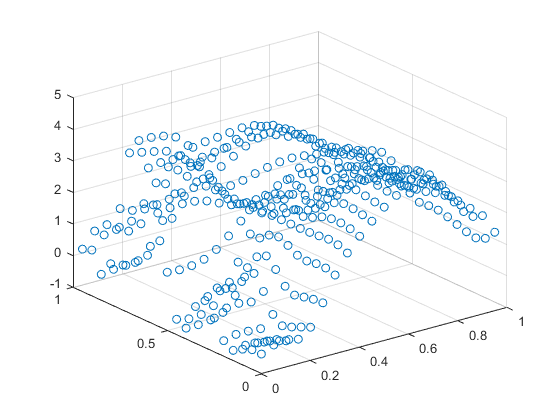

scatter3(x,y,output)

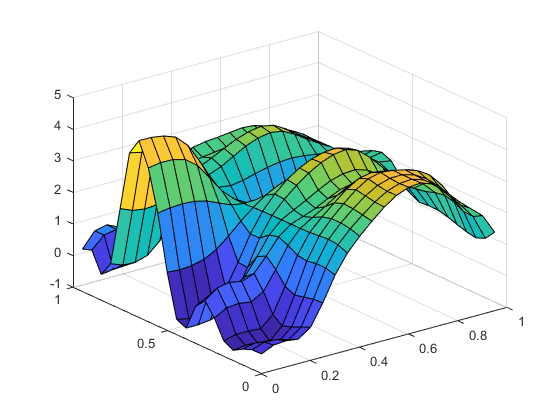


surf(t,t,reshape(output,[timesteps timesteps]));

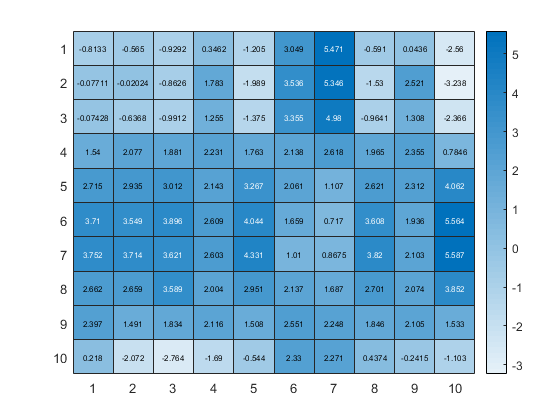


weightz = reshape(G{1},nnn,[])*G{2};

heatmap(weightz);

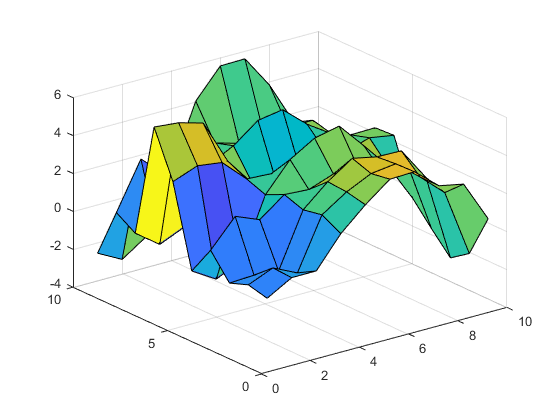

surf(1:nnn,1:nnn,weightz');

% axis([2 9 2 9 -5 5])
% [X,Y] = meshgrid(tfeaturez(:,1),tfeaturez(:,2));
% 
% tri = delaunay(tfeaturez(:,1),tfeaturez(:,2));
% h = trisurf(tri, tfeaturez(:,1), tfeaturez(:,2), tlabels);
% scatter3(tfeaturez(:,1), tfeaturez(:,2), tlabels)

% h = trisurf(tri, tfeaturez(:,1), tfeaturez(:,2), output);
% scatter3(tfeaturez(:,1), tfeaturez(:,2), output)

% axis vis3d

[tlabelz, id] = sort(tlabels);
[zetaz, idez] = sort(zeta);

tempiz = output(testz);
tempizeta = output(trainz);

outputsrt = tempiz(id);

outputsrtz = tempizeta(idez);

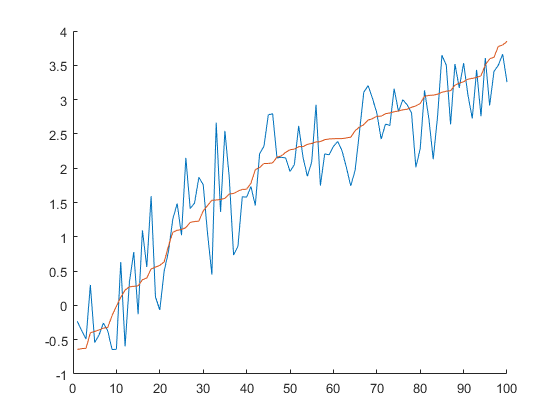



figure
hold on
plot(outputsrt)
plot(tlabelz)
hold off

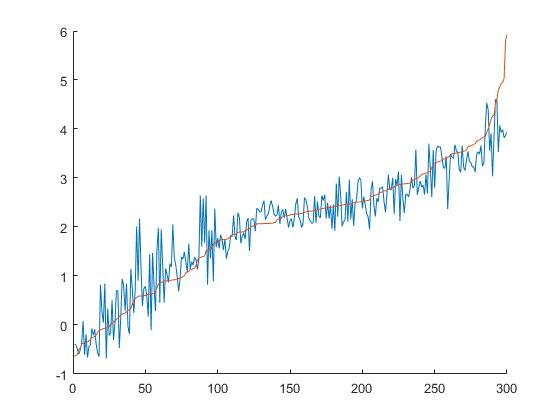

figure
hold on
plot(outputsrtz)
plot(zetaz)
hold off



erboi = (outputsrt-tlabelz);
% plot(erboi)
pererror = sum(abs(erboi))/Nt

pererror = 0.0928

relerror = sum(abs(erboi)/sum(abs(tlabelz)))

relerror = 0.1859

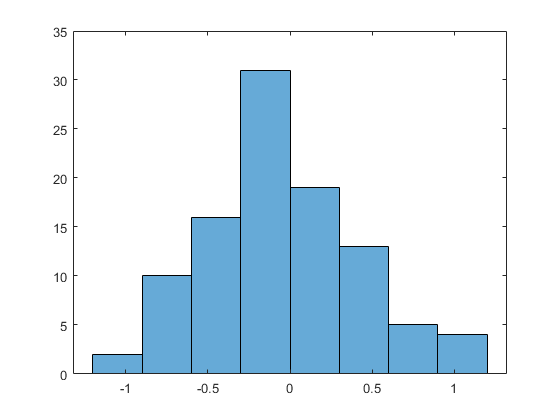

histogram((erboi)')

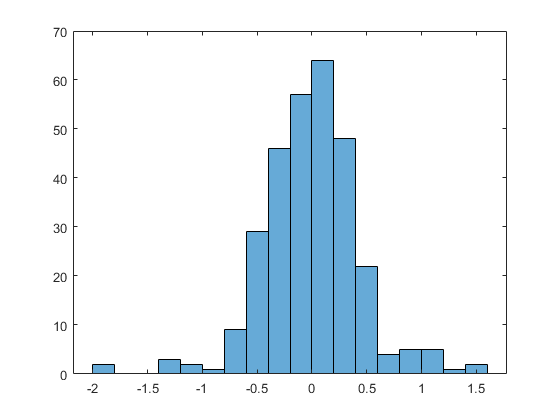



erboiz = (outputsrtz-zetaz);
histogram((erboiz)')


norm(erboi)/numel(erboi)

ans = 0.0466

norm(erboiz)/numel(erboiz)

ans = 0.0257


% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end

% 
% difforder=2
% P = diff(eye(nnn),difforder)
% PP = P'*P
% 
% sweepindex=4
% tic
% for j=1:d
% Csize = TN.n(j,:);
% 
% Dm = reshape(permute(G{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
% mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
% DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
% PD = P*Dm;
% DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
% DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
% eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
% eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
% end
% eyez{d+1}=1;
% 
% for p= 1:d
%     Dsize = TN.n(sweepindex,:);   
%         if sweepindex==p
%             D1 = eyez{sweepindex};
%             D2 = PP(:);
%             D3 = eyez{sweepindex+1};
% 
%         elseif sweepindex<p
%             D1 = eyez{sweepindex};  
%             D2 = eyep{sweepindex};   
%             D3= DWD{p}*eyez{p+1};           
%             for it=(p-1):-1:(sweepindex+1)               
%                 D3 = DD{it}*D3;
%             end                        
%          
%         elseif sweepindex>p   
%             D1= eyez{p}'*DWD{p};
%             for it=(p+1):(sweepindex-1)               
%                 D1 = D1*DD{it};
%             end
%             D1=D1';
%             D2 = eyep{sweepindex};   
%             D3= eyez{sweepindex+1}; 
% 
%         end
%     
%     WW = kron(D3, kron(D2, D1));
%     Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
%     W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]);
%     
% end
% 
% WWW = W{1};
% for s =2:d
%     WWW = WWW + W{s};
% end
% 
% imagesc(WWW)
% % imagesc(W{d})
% toc
% 
% 
% % 
% % 
% % W =  permute(reshape(WW, c1 c1 c2 c2 c3 c3), [1 3 5 2 4 6]
% % reshape(W, [c1*c2*c3 c4*c5*c6])

% 
% new = kron([2 2 2]',[1 2 3]')
% lef = [1 2 3]
% mid =[1 2 3; 4 5 6; 7 8 9]
% right =[2 2 2]'
% lef*mid *right
% 
% new(:)'*mid(:)
% 